## **Driver test program to check Clothoids library**

**Test clothoid**

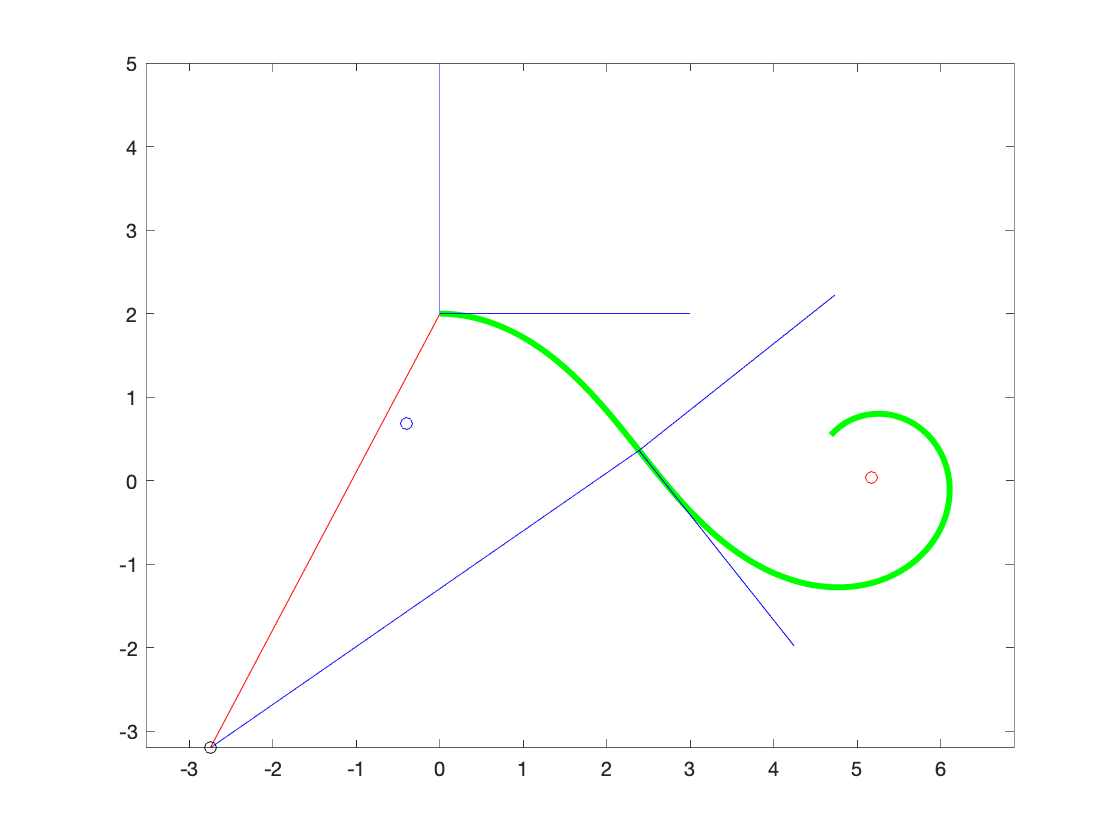

% check constructors
x0     = 0;
y0     = 2;
theta0 = 0;
kappa0 = -0.6;
dk     = 0.2;
L      = 10;
L1     = ClothoidCurve( x0, y0, theta0, kappa0, dk, L );

L1.plot(1000,'Color','green','LineWidth',3);
hold on;

[xx,yy,th,kk] = L1.evaluate(-kappa0/dk);
plot( [xx,xx+3*cos(th)],[yy,yy+3*sin(th)],'-b' );
plot( [xx,xx-3*sin(th)],[yy,yy+3*cos(th)],'-b' );

[xx1,yy1,th1,kk1] = L1.evaluate(0);
plot( [xx1,xx1+3*cos(th1)],[yy1,yy1+3*sin(th1)],'-b' );
plot( [xx1,xx1-3*sin(th1)],[yy1,yy1+3*cos(th1)],'-b' );

XXX = -2.75;
YYY = -3.2000000000000001776;

plot([XXX,xx],[YYY,yy],'-b');
plot([XXX,xx1],[YYY,yy1],'-r');

plot(XXX,YYY,'ok');
[xp,yp,xm,ym] = L1.infinity();

plot(xp,yp,'or');
plot(xm,ym,'ob');

axis equal;

%
L1.delete();